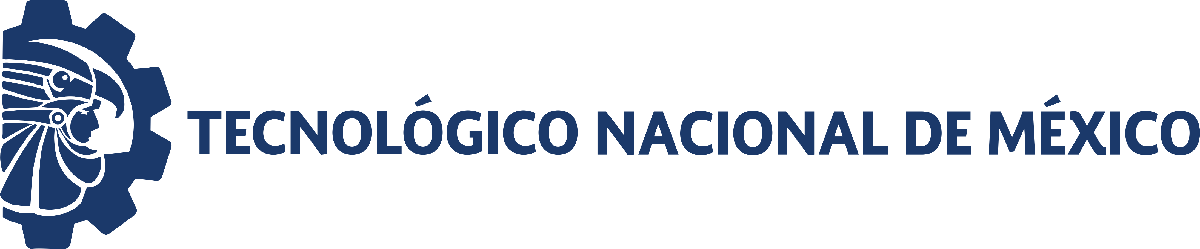                                 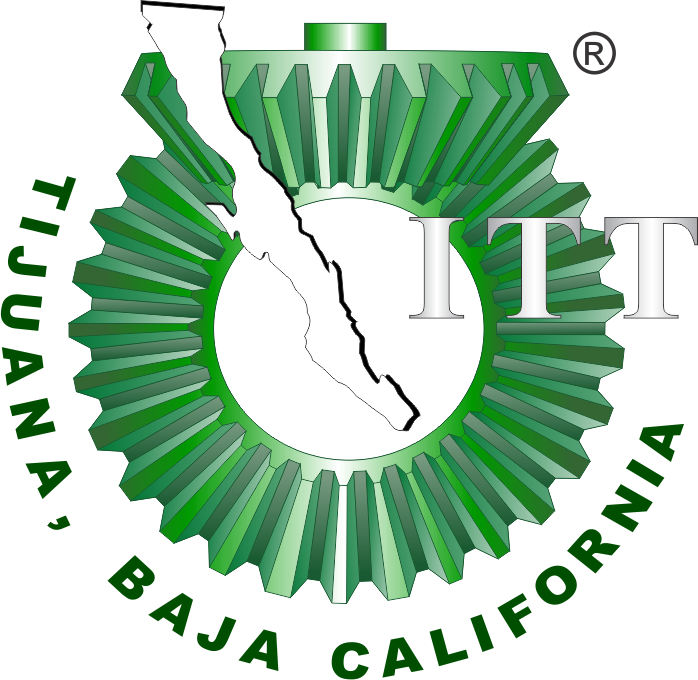

# Práctica 3: Sistema Muscoecqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

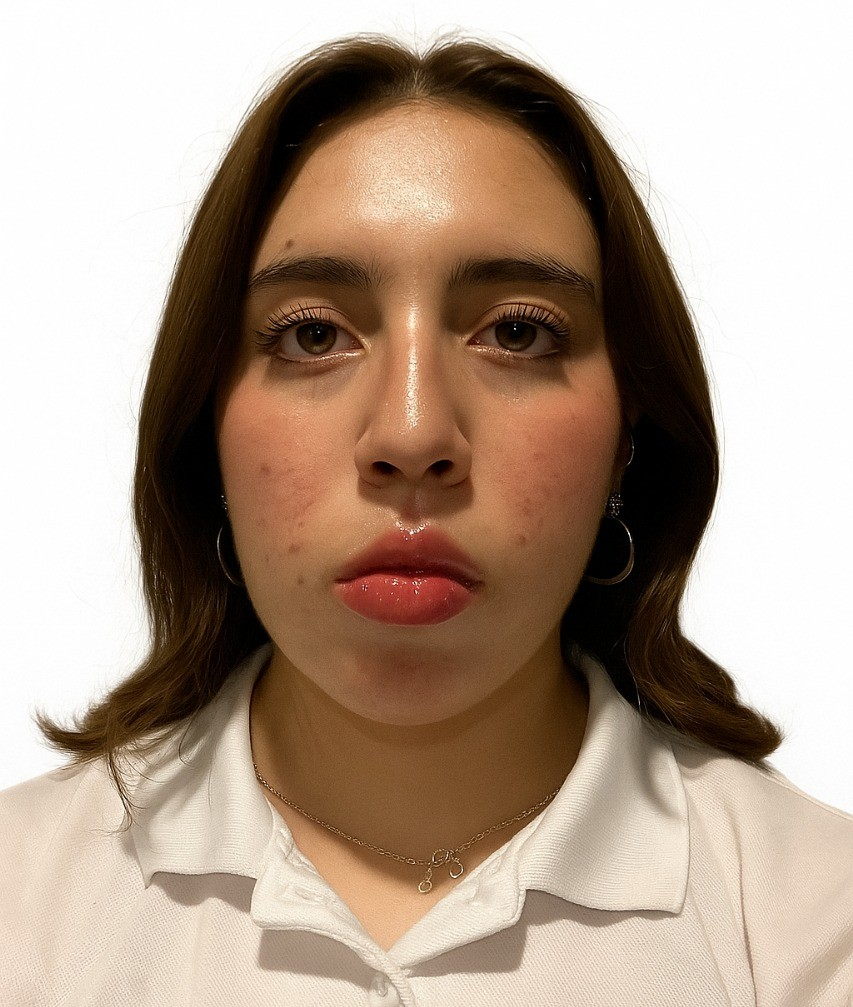

Nombre del alumno: **Claudia Ximena Castro Castro**

Número de control: **22212252**

Correo institucional: **l22212252@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Respuesta de sistema musculoesquelético 

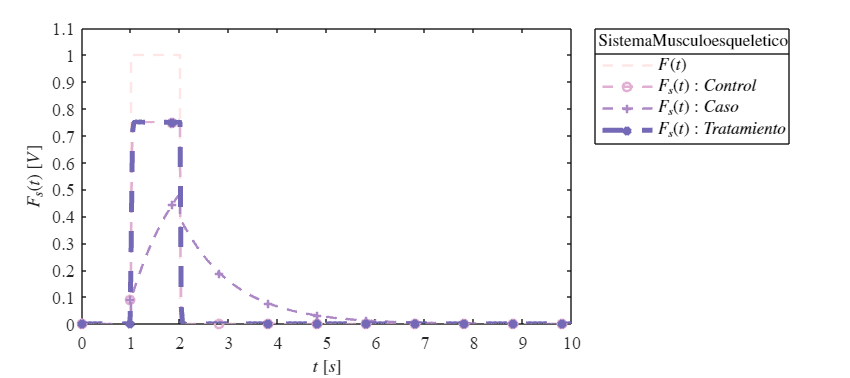

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SimulacionPractica3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
X = sim(file,parameters);
plotsignals(X.t,X.Fs,X.Fs1,X.Fs2,X.Fs3)

## Respuesta de la señal cardiovascular en lazo abierto

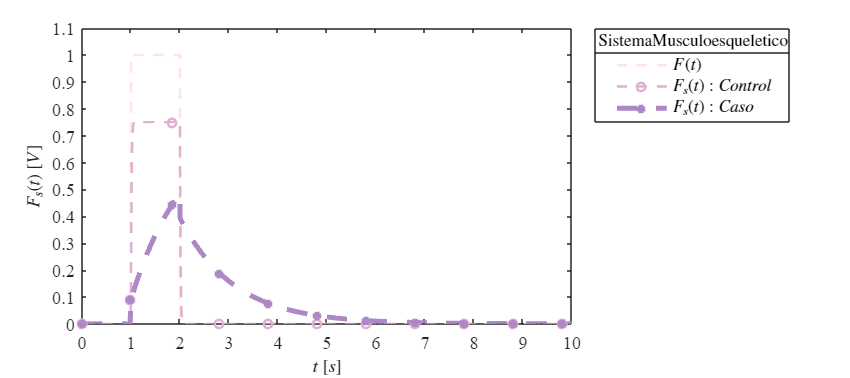

X2 = sim(file,parameters);
plotsignals2(X2.t,X2.Fs,X2.Fs1,X2.Fs2)

## Función: Respuesta a las señales

function plotsignals(t, Fs, Fs1, Fs2, Fs3)
   set(figure(), 'Color', 'w')
   set(gcf, 'units', 'centimeters', 'position', [1,1,18,8] )
   set(gca, 'FontName', 'Times New Roman', 'FontSize',11)
   hold on; grid off; box on;
   mycolors = [1.000, 0.902, 0.902;
               0.882, 0.686, 0.820;
               0.678, 0.533, 0.776;
               0.455, 0.412, 0.714;
               0.392, 0.498, 0.737;
               0.568, 0.678, 0.784;
               ];
   colororder(mycolors)

   p=plot(t, Fs, '--', t,Fs1, '--o',t,Fs2, '--+',t,Fs3,'--x', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
  set(p(4),'LineWidth',3);
   L = legend('$F(t)$','$F_{s}(t): Control$', '$F_{s}(t): Caso$', '$F_{s}(t): Tratamiento$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
   title (L, 'SistemaMusculoesqueletico', 'FontSize',10)


   xlabel('$t$ $[s]$', 'Interpreter','Latex', 'FontSize',11)
   ylabel('$F_s(t)$ $[V]$', 'Interpreter','Latex', 'FontSize',11)

   xlim([0,10]); xticks(0:1:10);
   ylim([0,1.1]); yticks(0:0.1:1.1);

exportgraphics(gcf,'SistemaMusculoesqueletico.pdf','ContentType','vector')
exportgraphics(gcf,'SistemaMusculoesqueletico.png','ContentType','vector')
end

function plotsignals2(t, Fs, Fs1, Fs2)
   set(figure(), 'Color', 'w')
   set(gcf, 'units', 'centimeters', 'position', [1,1,18,8] )
   set(gca, 'FontName', 'Times New Roman', 'FontSize',11)
   hold on; grid off; box on;
   mycolors = [1.000, 0.902, 0.902;
               0.882, 0.686, 0.820;
               0.678, 0.533, 0.776;
               0.455, 0.412, 0.714;
               0.392, 0.498, 0.737;
               0.568, 0.678, 0.784;
               ];
   colororder(mycolors)

   p=plot(t, Fs, '--', t, Fs1, '--o',t,Fs2, '--+', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
  set(p(3),'LineWidth',3);
   L = legend('$F(t)$','$F_{s}(t): Control$', '$F_{s}(t): Caso$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
   title (L,'SistemaMusculoesqueletico', 'FontSize',10)


   xlabel('$t$ $[s]$', 'Interpreter','Latex', 'FontSize',11)
   ylabel('$F_s(t)$ $[V]$', 'Interpreter','Latex', 'FontSize',11)

   xlim([0,10]); xticks(0:1:10);
   ylim([0,1.1]); yticks(0:0.1:1.1);


exportgraphics(gcf,'LazoAbierto.pdf','ContentType','vector')
exportgraphics(gcf,'LazoAbierto.png','ContentType','vector')
end














